# **Homework 1 Orbital Dynamics**

Student 1: Mario Barrantes Mellado 100471762

Student 2: Artem Lorenzo Lymar 100471784

Data of the problem:

close all; clear all; clc;

m = 2000; % Mass of spacecraft - [kg]

phi_gs = deg2rad(50); % Angle of position of Ground Station w/ respect to equatorial plane - [rad]
h_gs = 0.8;  % Altitude of Ground Station (from Sea Level) - [m]
R_earth = 6371; % Radius of the Earth - [km]


mu_E = 3.986e5; % [km^3/m^2]
R_S = R_earth + h_gs; % Radius of Ground Station - [km]

t0 = 22.5; % [h]
ti = 9; % [h] - Time @ which spacecraft crossed equatorial plane
t = (t0 - ti)*3600; % Time since spacecraft crossed equatorial plane - [s]

r1 = [5369.09; 2332.14; 656.480]; % Initial position - [km]
v1 = [-3.37027; 4.90364; 0.106703]; % Initial velocity - [km/s]

### a) Expressing ECI base from SEZ base.

In this first section, the objective is to transform the position and velocity vectors that are initially expressed in the South-East-Zenith reference frame ($S_1$), i.e., the station-based reference frame,  into the Earth-Centered Inertial reference frame ($S_0$) . For doing this, the longitude and latitude rotations are performed.

The rotation speed of S1 with respect to S0 is the one of the Earth (7.29216e-5 rad/s) and the latitude of the ground station ($\phi$) is 50º. The statement gives the position and velocity exactly at 22:30 (local time at the station), and the longitude angle ($\lambda$) can be obtained from knowing that the station crossed the Equatorial Plane ($\lambda=0$)  at 9:00.

% Implementations of SEZ2ECI function:

[r0,v0,lambda,R_tot] = functionshw1.SEZ2ECI(r1,v1,R_S,phi_gs,t) % This is correct, no more revision.

r0 = 1.0e+03 *

   -7.0281
   -5.5256
    1.9328


v0 =     4.6357
   -4.0404
    2.2481


lambda = 3.5440

R_tot =    -0.7049    0.3916   -0.5915
   -0.3000   -0.9201   -0.2517
   -0.6428         0    0.7660


### b) Classical orbital elements: $a$, $e$, $\Omega$, $i$, $\omega$ and $\theta_0$. Plot of orbit.

[a, e, Omega, i, omega, theta_0] = functionshw1.rv2coe(r0,v0,mu_E)

a = 9.0000e+03

e = 0.1000

Omega = 3.3258

i = 0.4363

omega = 2.3562

theta_0 = 4.4506

[Omega_deg, i_deg, omega_deg, theta_0_deg] = functionshw1.rad2deg(Omega, i, omega, theta_0)

Omega_deg = 190.5539

i_deg = 25.0000

omega_deg = 135.0005

theta_0_deg = 254.9995

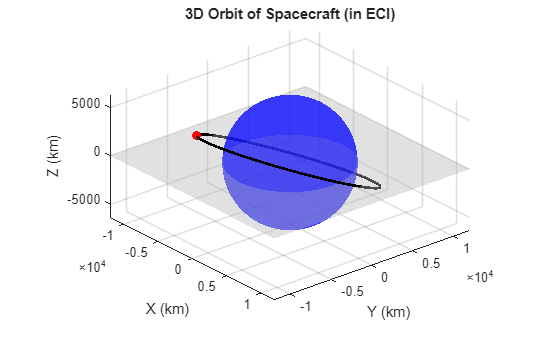

% Plot of orbit
theta = linspace(0,2*pi,200);
r = (a * (1 - e^2)) ./ (1 + e * cos(theta)); % Vector containing all positions across elliptical orbit

x_p = r .* cos(theta);
y_p = r .* sin(theta);
z_p = zeros(size(theta));

% Using the angles calculated by rv2coe
R = [cos(Omega)*cos(omega)-sin(Omega)*sin(omega)*cos(i), -cos(Omega)*sin(omega)-sin(Omega)*cos(omega)*cos(i),  sin(Omega)*sin(i);
     sin(Omega)*cos(omega)+cos(Omega)*sin(omega)*cos(i), -sin(Omega)*sin(omega)+cos(Omega)*cos(omega)*cos(i), -cos(Omega)*sin(i);
     sin(omega)*sin(i),                                   cos(omega)*sin(i),                                   cos(i)];

% Transform coordinates from perifocal to ECI frame
r_orbit = R * [x_p; y_p; z_p];

% Generate the Plot
figure;
plot3(r_orbit(1,:), r_orbit(2,:), r_orbit(3,:), 'LineWidth', 2, 'Color', 'k');
grid on; hold on;
axis equal;

% 6. Add the Earth to the center using your R_earth variable
[sx, sy, sz] = sphere(50);
surf(sx*R_earth, sy*R_earth, sz*R_earth, 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.5); 

% Optional: Plot the initial position vector (r0) to verify it lies on the orbit
plot3(r0(1), r0(2), r0(3), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);

% Add the Equatorial Plane
plane_limit = 12000; % Size in km, wide enough to cover the apogee
[X_eq, Y_eq] = meshgrid([-plane_limit plane_limit]);
Z_eq = zeros(size(X_eq)); % The equatorial plane sits exactly at Z = 0

% Plot the surface. FaceAlpha makes it semi-transparent so you can see the orbit beneath it.
surf(X_eq, Y_eq, Z_eq, 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none', 'FaceAlpha', 0.4);

xlabel('X (km)'); 
ylabel('Y (km)'); 
zlabel('Z (km)');
title('3D Orbit of Spacecraft (in ECI)');
view(50, 25);

### c) Local time at the station when the spacecraft reaches $\theta = \theta_0 + \pi/2$. Position and velocity of the spacecraft in ECI $6h$ after the initial observation. Position and velocity vectors of the spacecraft in SEZ at that instant.

% from 2bp13
delta_theta = pi/2;
n_e = sqrt(mu_E/a^3);

[t_f] = functionshw1.deltatheta2t(theta_0, delta_theta, mu_E, a, e, t0)

t_f = 23.0343

% from 2bp12
delta_t = 6; %[h]

[theta_f] = functionshw1.t2theta(theta_0, mu_E, a, e, delta_t)

theta_f = 1.9599

[rf_0, vf_0]  = functionshw1.coe2rv(a, e, Omega, i, omega, theta_f, mu_E)

rf_0 = 1.0e+03 *

    2.0961
    8.2669
   -3.6107


vf_0 =    -6.1079
    1.6782
   -1.2910


tf = (t0 + delta_t - ti)*3600; % Time since spacecraft crossed equatorial plane - [s]

[rf_1,vf_1, v1_0] = functionshw1.ECI2SEZ(rf_0, vf_0, R_S, phi_gs, tf) % revise if results are correct

rf_1 = 1.0e+04 *

   -0.2860
    0.5195
   -1.3485


vf_1 =    -1.9114
   -4.4528
   -3.2891


v1_0 =    -5.5051
    1.5253
   -1.2910


### d) Payload of 500kg released after 6h with velocity $\bar{v} = [-6.0, 3, -1.6] \ \text{km/s}$

For solving this section we will apply conservation of linear momentum: $$$m_{total} \vec{v}_{initial} = m_{sat} \vec{v}_{sat} + m_{payload} \vec{v}_{payload}$$$

m_payload = 500; % [kg]
m_sat_new = m - m_payload; % [kg] -> 1500 kg remaining

v_payload = [-6.0; 3.0; -1.6]; % [km/s] in ECI

% Conservation of Linear Momentum: m * vf_0 = m_sat * v_sat_new + m_payload * v_payload
v_sat_new = (m * vf_0 - m_payload * v_payload) / m_sat_new;

r_sat_new = rf_0; % since position doesn't change the instant the payload is released

% new classical orbital elements - rv2coe developed in question b)
[a_new, e_new, Omega_new, i_new, omega_new, theta_new] = functionshw1.rv2coe(r_sat_new, v_sat_new, mu_E)

a_new = 8.7820e+03

e_new = 0.0612

Omega_new = 3.3552

i_new = 0.4418

omega_new = 1.5912

theta_new = 2.6983

[Omega_new_deg, i_new_deg, omega_new_deg, theta_new_deg] = functionshw1.rad2deg(Omega_new, i_new, omega_new, theta_new)

Omega_new_deg = 192.2394

i_new_deg = 25.3111

omega_new_deg = 91.1671

theta_new_deg = 154.6015

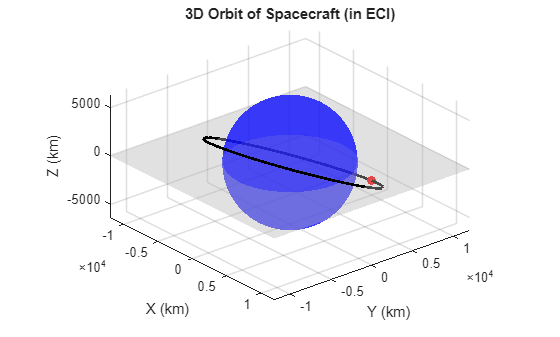

% Plot of orbit
theta_new = linspace(0,2*pi,200);
r = (a_new * (1 - e_new^2)) ./ (1 + e_new * cos(theta_new)); % Vector containing all positions across elliptical orbit

x_p = r .* cos(theta_new);
y_p = r .* sin(theta_new);
z_p = zeros(size(theta_new));

% Using the angles calculated by rv2coe
R = [cos(Omega_new)*cos(omega_new)-sin(Omega_new)*sin(omega_new)*cos(i_new), -cos(Omega_new)*sin(omega_new)-sin(Omega_new)*cos(omega_new)*cos(i_new),  sin(Omega_new)*sin(i_new);
    sin(Omega_new)*cos(omega_new)+cos(Omega_new)*sin(omega_new)*cos(i_new), -sin(Omega_new)*sin(omega_new)+cos(Omega_new)*cos(omega_new)*cos(i_new), -cos(Omega_new)*sin(i_new);
    sin(omega_new)*sin(i_new),                                   cos(omega_new)*sin(i_new),                                   cos(i_new)];

% Transform coordinates from perifocal to ECI frame
r_orbit = R * [x_p; y_p; z_p];

% Generate the Plot
figure;
plot3(r_orbit(1,:), r_orbit(2,:), r_orbit(3,:), 'LineWidth', 2, 'Color', 'k');
grid on; hold on;
axis equal;

% 6. Add the Earth to the center using your R_earth variable
[sx, sy, sz] = sphere(50);
surf(sx*R_earth, sy*R_earth, sz*R_earth, 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.5); 

% Optional: Plot the initial position vector (r0) to verify it lies on the orbit
plot3(rf_0(1), rf_0(2), rf_0(3), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);

% Add the Equatorial Plane
plane_limit = 12000; % Size in km, wide enough to cover the apogee
[X_eq, Y_eq] = meshgrid([-plane_limit plane_limit]);
Z_eq = zeros(size(X_eq)); % The equatorial plane sits exactly at Z = 0

% Plot the surface. FaceAlpha makes it semi-transparent so you can see the orbit beneath it.
surf(X_eq, Y_eq, Z_eq, 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none', 'FaceAlpha', 0.4);

xlabel('X (km)'); 
ylabel('Y (km)'); 
zlabel('Z (km)');
title('3D Orbit of Spacecraft (in ECI)');
view(50, 25);

### e) ΔV required to circularize the orbit of the spacecraft at its new pericenter

% Need to go from elliptical orbit to circular orbit when satellite is at the pericenter
[rp_new, ra_new] = functionshw1.coe2pa(a_new, e)

rp_new = 7.9038e+03

ra_new = 9.6602e+03

deltaV = sqrt((2*mu_E)/rp_new - mu_E/a_new) - sqrt(mu_E/rp_new) % [km/s]

deltaV = 0.3466

## Discussion

(Complete your report with any comments you may like to add)

## Copilot AI

Please add a short paragraph at the end of each homework about this: did you use Copilot? How and where exactly? Did you need to modify the suggestions afterward? What was your experience like?

For this homework Copilot was use for creating the plot of the orbit around the Earth